Rubén Vera Martínez, NIA: 241456

Sara Soriano Rossa, NIA: 240007

alpha = 0.017;

**PROBLEM 1**

**a) Indicate what method would you use to answer the research questions of this Problem. Indicate the assumptions that should be fulfilled (make sure to specify them clearly and adjusted to the data to be used; e.g. statements like "independence" without further clarification will not be accepted). For this problem, you do not need to test whether the assumptions hold; we will assume that they do.**

Para este problema hemos decidido aplica el método 2-way factorial ANOVA.

Assumptions:

- Normal distribution of variables

- Homoscedasticity

- Independence of variables

**b) Test whether there is a significant interaction effect. Clearly state: i) the corresponding null and alternative hypotheses, ii) your conclusion and iii) the relevant numerical details.**

**(i)** Las hipótesis que necesitamos para comprobar si hay interacción o no son las siguientes:

    
$$H_{03} :\gamma_{\textrm{lk}} =0\;\;\forall \textrm{lk},\;\;\;\;\;\;\;\;\;\;\;\;H_{\textrm{A3}} :\;\;\exists l,l^{\prime } ,k,k^{\prime } :\gamma_{\textrm{lk}} \not= \gamma_{l^{\prime } k^{\prime } }$$


    donde $\gamma_{\textrm{lk}}$ es la interacción que puede haber en cada celda, la hipotesis nula por lo tanto, si no puede ser rechazada significará que no hay interacción en las celdas y por lo tanto tendremos main effects. En caso que la rechacemos, es decir que haya alguna celda donde el resultado de la media sea diferente de lo esperado observando en las demás celdas. Es decir, si por ejemplo para todos los años, la media de los que han pasado el final es mayor a los que no, y hay un año donde no sucede esto habrá una interacción.

**(ii y iii)**

x = SMSamplesMarks20192021{:, "ContinuousEvaluation"};
not_passed_2019 = SMSamplesMarks20192021{[1:13], "ContinuousEvaluation"};
passed_2019 = SMSamplesMarks20192021{[14:26], "ContinuousEvaluation"};
not_passed_2020 = SMSamplesMarks20192021{[27:39], "ContinuousEvaluation"};
passed_2020 = SMSamplesMarks20192021{[40:52], "ContinuousEvaluation"};
not_passed_2021 = SMSamplesMarks20192021{[53:65], "ContinuousEvaluation"};
passed_2021 = SMSamplesMarks20192021{[66:78], "ContinuousEvaluation"};

passed = [passed_2019 passed_2020 passed_2021];
not_passed = [not_passed_2019 not_passed_2020 not_passed_2021];
measures_2019 = [not_passed_2019, passed_2019];
measures_2020 = [not_passed_2020, passed_2020];
measures_2021 = [not_passed_2021, passed_2021];

mean_not_passed_2019 = mean(not_passed_2019, 1);
mean_passed_2019 = mean(passed_2019, 1);
mean_not_passed_2020 = mean(not_passed_2020, 1);
mean_passed_2020 = mean(passed_2020, 1);
mean_not_passed_2021 = mean(not_passed_2021, 1);
mean_passed_2021 = mean(passed_2021, 1);

mean_passed = mean([mean_passed_2019, mean_passed_2020, mean_passed_2021]);
mean_not_passed = mean([mean_not_passed_2019, mean_not_passed_2020, mean_not_passed_2021]);

mean_2019 = mean([mean_not_passed_2019, mean_passed_2019]);
mean_2020 = mean([mean_not_passed_2020, mean_passed_2020]);
mean_2021 = mean([mean_not_passed_2021, mean_passed_2021]);

mean_col_x = [mean_not_passed mean_passed];
mean_row_x = [mean_2019; mean_2020; mean_2021];
mean_x = mean(x, "all");


lk = [mean_not_passed_2019 mean_passed_2019; mean_not_passed_2020 mean_passed_2020; mean_not_passed_2021 mean_passed_2021];
tau = mean(lk, 2) - mean_x;
beta = mean(lk, 1) - mean_x;
mu_tau_beta = mean_x+tau+beta;
gamma = lk - mu_tau_beta;

g = 3;
b = 2;
n = size(x, 1)/(g*b);
N = n*b*g;

SS_B1 =n*b*sum(tau.^2)

SS_B1 = 3.3701

SS_B2 = g*n*sum(beta.^2)

SS_B2 = 20.4618

SS_W = sum(sum((measures_2019-lk(1,:)).^2)) + sum(sum((measures_2020-lk(2,:)).^2)) + sum(sum((measures_2021-lk(3,:)).^2))

SS_W = 62.7404

SS_int = n * sum(sum(gamma.^2))

SS_int = 0.4770

estimator_fint = (SS_int/((g-1)*(b-1)))/(SS_W/(N-(b*g)))

estimator_fint = 0.2737

critic = finv(1-alpha, ((g-1)*(b-1)), N-(b*g)) 

critic = 4.3141


if (estimator_fint > critic)
    disp("There is interaction.");
else 
    disp("There is no interaction.");
end

There is no interaction.


Una vez testeado , vemos, a partir el resultado obtenido no hay interacción, ya que el estimador es menor al valor crítico calculado.

**c) Based on your results from (b), indicate whether further analysis of these data should be based on assessing main effects or simple effects. Justify adequately, including any additional analysis that you believe necessary to provide an adequate answer**

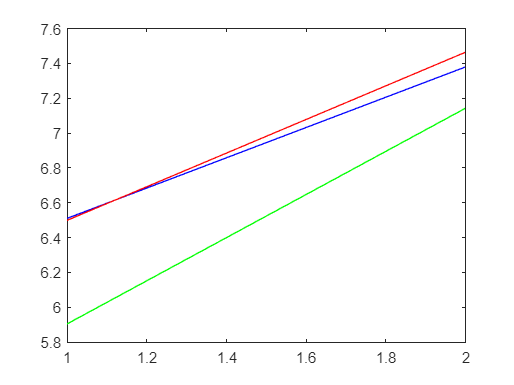

plot(lk(1,:), Color="B") %2019
hold on
plot(lk(2,:), Color="R") %2020
plot(lk(3,:), Color="G") %2021
hold off

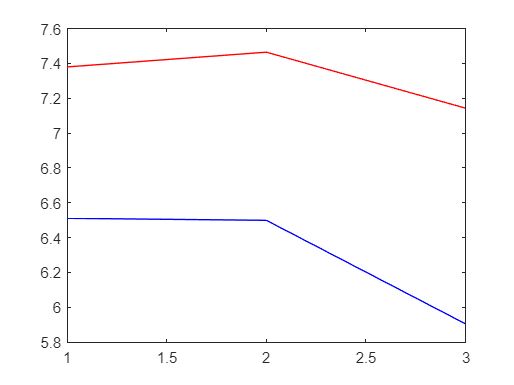


plot(lk(:,1), Color="B") %Not passed
hold on
plot(lk(:,2), Color="R") %Passed
hold off

Dado que estos plots son a partir de samples, no veremos una paralelidad al 100%. Pero vemos que la tendencia en ambos plots es que todas las lineas sean paralelas entre ellas, por la cual cosa demostramos y afirmamos con mayor seguridad que no hay interacción. Ya que, en caso de que sean paralelas significa que todas siguen la misma orientación. Es decir, que no hay una celda donde el resultado sea diferente a lo esperado viendo las demás y por lo tanto no podemos rechazar la hipotesis nula.

Basado en nuestros resultados y nuestras justificaciones en (b) y en los plots anteriores, como no hay interacción hemos de pasar a calcular los Main Effects. 

**d) Proceed to analyze main or simple effects, according to your answer in (c). In all cases provide your conclusions, clearly indicating what they imply for the two research questions proposed in this Problem.**

Como estamos en el caso de main effects tendremos las siguientes hipótesis:


$$\begin{array}{l}
H_{01} :\tau_l =0\;\;\;\;\forall l\;\;,\;\;\;\;\;\;\;\;\;\;\;\;\;H_{\textrm{A1}} :\;\;\exists l,l^{\prime } :\tau_l \not= \tau_{l^{\prime } } \\
H_{02} :\beta_k =0\;\;\;\forall k\;,\;\;\;\;\;\;\;\;\;\;\;\;\;H_{\textrm{A2}} :\;\exists k,k^{\prime } :\beta_k \not= \beta_{k^{\prime } } \;
\end{array}$$


F1 = ((SS_B1)/(g-1))/(SS_W/(N-g*b))

F1 = 1.9337

F2 = ((SS_B2)/(b-1))/(SS_W/(N-g*b))

F2 = 23.4816


F_critic1 = finv(1-alpha, g-1, N-g*b) 

F_critic1 = 4.3141

F_critic2 = finv(1-alpha, b-1, N-g*b)

F_critic2 = 5.9705


if (F1 > F_critic1)
    disp("We reject the null hypothesis 1 at significance level 0.017.");
else 
    disp("We cannot reject the null hypothesis 1 at significance level 0.017.");
end

We cannot reject the null hypothesis 1 at significance level 0.017.



if (F2 > F_critic2)
    disp("We reject the null hypothesis 2 at significance level 0.017.");
else 
    disp("We cannot reject the null hypothesis 2 at significance level 0.017.");
end

We reject the null hypothesis 2 at significance level 0.017.


A partir de estos tests vemos que:

- Hay diferencia de la nota de la evaluación continua en función de si has aprobado el examen final o no.

- No hay diferencia de la nota de la evaluación continua en función de en que año hiciste el curso, por lo que había cursos más dificiles que otros.

A continuación miraremos que grupo es el que difiere en cada caso:

M = g*(g-1)/2;
tcrit = tinv(alpha/(2*M), N-g)

tcrit = -2.8485

denominator = sqrt((SS_W/(N-g))*(1/n+1/n));
T_2019 = (mean_passed_2019-mean_not_passed_2019)/denominator

T_2019 = 2.4230

T_2020 = (mean_passed_2019-mean_not_passed_2020)/denominator

T_2020 = 2.4552

T_2021 = (mean_passed_2021-mean_not_passed_2021)/denominator

T_2021 = 3.4522

Por lo tanto, vemos que no podemos rechazar que hay una diferencia de la nota de la evaluación continua en función de si has aprobado el examen final o no en el 2019 y 2020. Pero, en cambio, vemos que en el 2021 si la hay. Por lo tanto, es este grupo el que nos ha hecho rechazar en el primer paso.

alpha = 0.017;

**PROBLEM 2**

**a)  Indicate what method would you use to answer the research questions of this Problem. Indicate the assumptions that should be fulfilled (make sure to specify them clearly and adjusted to the data to be used; e.g. statements like "independence" without further clarification will not be accepted). For this problem, you do not need to test whether the assumptions hold; we will assume that they do.**

Para este problema el método que empraremos será el Two-Way Factorial MANOVA. Por lo tanto las asunciones para dicho método son las siguientes:

- Normal distribution of variables

- Homoscedasticity

- Independence of variables

**b) Test whether there is a significant interaction effect. Clearly state: i) the corresponding null and alternative hypotheses, ii) your conclusion and iii) the relevant numerical details.**

**(i) **Para el Two-Way MANOVA hay distintas hipótesis, pero como en este apartado nos piden solamente la asuncion que corresponde al efecto de interacción, las hipótesis son las siguientes:

    
$$H_{03} :\overrightarrow{\gamma_{\textrm{lk}} } =0\;\;\forall \textrm{lk},\;\;\;\;\;\;\;\;\;\;\;\;H_{\textrm{A3}} :\;\;\exists l,l^{\prime } ,k,k^{\prime } :\overrightarrow{\gamma_{\textrm{lk}} } \not= \overrightarrow{\gamma_{l^{\prime } k^{\prime } } }$$


    donde $\overrightarrow{\gamma_{\textrm{lk}} }$ es la interacción que puede haber en cada celda, la hipotesis nula por lo tanto, si no puede ser rechazada significará que no hay interacción en las celdas y, por lo tanto, tendremos main effects. En caso que la rechacemos, es decir, que haya alguna celda donde el resultado de la media sea diferente de lo esperando observando los efectos en las demás celdas. Es decir, si por ejemplo para todos los años, la media de los que han pasado el final es mayor a los que no, y hay un año donde no sucede esto habrá una interacción.

**(iii)**

x = SMSamplesMarks20192021{:, ["Lab1", "Lab2", "Lab4", "Lab5", "Lab6"]};
not_passed = SMSamplesMarks20192021{[1:13, 27:39, 53:65], ["Lab1", "Lab2", "Lab4", "Lab5", "Lab6"]};
passed = SMSamplesMarks20192021{[14:26, 40:52, 66:78], ["Lab1", "Lab2", "Lab4", "Lab5", "Lab6"]};
measures_2019 = SMSamplesMarks20192021{[1:26], ["Lab1", "Lab2", "Lab4", "Lab5", "Lab6"]};
measures_2020 = SMSamplesMarks20192021{[27:52], ["Lab1", "Lab2", "Lab4", "Lab5", "Lab6"]};
measures_2021 = SMSamplesMarks20192021{[53:78], ["Lab1", "Lab2", "Lab4", "Lab5", "Lab6"]};

mean_2019_passed = mean(measures_2019(1:13, :), 1);
mean_2019_not_passed = mean(measures_2019(14:26, :), 1);
mean_2020_passed = mean(measures_2020(1:13, :), 1);
mean_2020_not_passed = mean(measures_2020(14:26, :), 1);
mean_2021_passed = mean(measures_2021(1:13, :), 1);
mean_2021_not_passed = mean(measures_2021(14:26, :), 1);

mean_passed = mean([mean_2019_passed; mean_2020_passed; mean_2020_passed]);
mean_not_passed = mean([mean_2019_not_passed; mean_2020_not_passed; mean_2020_not_passed]);

mean_2019 = mean([mean_2019_not_passed; mean_2019_passed]);
mean_2020 = mean([mean_2020_not_passed; mean_2020_passed]);
mean_2021 = mean([mean_2021_not_passed; mean_2021_passed]);
mean_years = [mean_2019;mean_2020; mean_2021];

mean_col_x = [mean_not_passed; mean_passed];
mean_row_x = [mean_2019; mean_2020; mean_2021];
mean_x = mean(x, 1);

tau = mean_row_x - mean_x;
beta = mean_col_x - mean_x;

g = 3;
b = 2;
n = size(x, 1)/(g*b);
N = n*b*g;
p = 5;

SS_B1 =n*b*transpose(tau)*tau

SS_B1 =    69.5374   25.3712  -27.4102   -4.3558   -7.5006
   25.3712   20.5417   -6.5406    1.5034    0.5997
  -27.4102   -6.5406   11.8654    2.6652    3.9796
   -4.3558    1.5034    2.6652    1.1204    1.3842
   -7.5006    0.5997    3.9796    1.3842    1.7954


SS_B2 = g*n*transpose(beta)*beta

SS_B2 =    55.3373   30.4593   11.2372   26.8300   37.4159
   30.4593   21.7759    4.6380   13.3070   17.9151
   11.2372    4.6380    2.7598    5.8995    8.4255
   26.8300   13.3070    5.8995   13.4344   18.9223
   37.4159   17.9151    8.4255   18.9223   26.7316


SS_int = 13 * ((transpose(mean_2019_passed-mean_passed-mean_2019+mean_x)*(mean_2019_passed-mean_passed-mean_2019+mean_x)) + (transpose(mean_2019_not_passed-mean_not_passed-mean_2019+mean_x)*(mean_2019_not_passed-mean_not_passed-mean_2019+mean_x)) + (transpose(mean_2020_passed-mean_passed-mean_2020+mean_x)*(mean_2020_passed-mean_passed-mean_2020+mean_x)) + (transpose(mean_2020_not_passed-mean_not_passed-mean_2020+mean_x)*(mean_2020_not_passed-mean_not_passed-mean_2020+mean_x)) + (transpose(mean_2021_passed-mean_passed-mean_2021+mean_x)*(mean_2021_passed-mean_passed-mean_2021+mean_x)) + (transpose(mean_2021_not_passed-mean_not_passed-mean_2021+mean_x)*(mean_2021_not_passed-mean_not_passed-mean_2021+mean_x)))

SS_int =    11.0953    5.7830   -1.3934    0.3534   -0.3388
    5.7830   13.3865    0.8022    3.8585    1.9814
   -1.3934    0.8022    2.7688    4.3651   -1.1434
    0.3534    3.8585    4.3651    7.6294   -1.7022
   -0.3388    1.9814   -1.1434   -1.7022    1.4142


SS_W = ((((transpose(measures_2019(1:13, :)-mean_2019_passed)) * (measures_2019(1:13, :)-mean_2019_passed)) + ((transpose(measures_2019(14:26,:)-mean_2019_not_passed)) * (measures_2019(14:26,:)-mean_2019_not_passed)))) + ((transpose(measures_2020(1:13, :)-mean_2020_passed) * (measures_2020(1:13, :)-mean_2020_passed)) + (transpose(measures_2020(14:26,:)-mean_2020_not_passed) * (measures_2020(14:26,:)-mean_2020_not_passed))) + ((transpose(measures_2021(1:13, :)-mean_2021_passed) * (measures_2021(1:13, :)-mean_2021_passed)) + (transpose(measures_2021(14:26,:)-mean_2021_not_passed) * (measures_2021(14:26,:)-mean_2021_not_passed)))

SS_W =   168.0935   50.4439   48.3569   46.4322   25.6413
   50.4439  165.5892   13.8595   40.6379   49.3513
   48.3569   13.8595  137.0182   34.5082   19.9106
   46.4322   40.6379   34.5082  204.8349   48.2461
   25.6413   49.3513   19.9106   48.2461  138.1981



dfinter =  (g-1) * (b-1);
dfW =  g*b*(n-1);

estimator = det(SS_W)/(det(SS_W+SS_int));
s = min(p, dfinter);
df1 = p*dfinter;
df2 = s*(dfW-(p-dfinter+1)/2)-((p*dfinter-2)/2);
estimator_f = ((1-estimator^(1/s))/df1)/((estimator^(1/s))/df2)

estimator_f = 1.5896


crit = finv(1-alpha,df1,df2)

crit = 2.2757


if (estimator_f > crit)
    disp("There is interaction.");
else 
    disp("There is no interaction.");
end

There is no interaction.


Una vez realizado el test, no podemos rechazar que no haya interacción ya que el estimador es menor al valor critico.

**c) Based on your results from (a), indicate whether further analysis of these data should be based on assessing main effects or simple effects. Justify adequately, including any additional analysis that you believe necessary to provide an adequate answer.**

En el apartado b) hemos visto que no hay interacción, por la cual cosa, podemos comparar main effects para ver si la diferencia de la nota en los labs se debe al año y de si apruebas o no el examen final o si solo depende de uno de los dos factores.

**d) Proceed to analyze main or simple effects, according to your answer in (b). In all cases provide your conclusions, clearly indicating what they imply for the two research questions proposed in this Problem.**

Como estamos en el caso de main effects tendremos las siguientes hipótesis:


$$\begin{array}{l}
H_{01} :\overrightarrow{\tau_l } =0\;\;\;\;\forall l\;\;,\;\;\;\;\;\;\;\;\;\;\;\;\;H_{\textrm{A1}} :\;\;\exists l,l^{\prime } :\overrightarrow{\tau_l } \not= \overrightarrow{\tau_{l^{\prime } } } \\
H_{02} :\overrightarrow{\beta_k } =0\;\;\;\forall k\;,\;\;\;\;\;\;\;\;\;\;\;\;\;H_{\textrm{A2}} :\;\exists k,k^{\prime } :\overrightarrow{\beta_k } \not= \overrightarrow{\beta_{k^{\prime } } } \;
\end{array}$$
 

donde $\overrightarrow{\tau_l }$son los vectores con la diferencia entre la media del factor 1 y la media global de los datos para cada uno de las filas del factor1 en este caso para cada uno de los 3 años

y $\overrightarrow{\beta_k }$ son los vectores con la diferencia entre la media del factor 2 y la media global de los datos para cada una de las columnas del factor2 en este caso para aquellos que han aprobado el examen final y aquellos que no.

dfb1 =  (g-1);
dfW =  g*b*(n-1);

estimator_wilks_1 = det(SS_W)/(det(SS_W+SS_B1));
s = min(p, dfb1);
df1 = p*dfb1;
df2 = s*(dfW-(p-dfb1+1)/2)-((p*dfb1-2)/2);
estimator_f1 = ((1-estimator_wilks_1^(1/s))/df1)/((estimator_wilks_1^(1/s))/df2)

estimator_f1 = 4.9390


crit_f1 = finv(1-alpha,df1,df2)

crit_f1 = 2.2757


if (estimator_f1 > crit_f1)
    disp("We reject the null hypothesis 1 at significance level 0.017.");
else 
    disp("We cannot reject the null hypothesis 1 at significance level 0.017.");
end

We reject the null hypothesis 1 at significance level 0.017.



dfb2 =  (b-1);
dfW =  g*b*(n-1);

estimator_wilks_2 = det(SS_W)/(det(SS_W+SS_B2));
s = min(p, dfb2);
df1 = p*dfb2;
df2 = s*(dfW-(p-dfb2+1)/2)-((p*dfb2-2)/2);
estimator_f2 = ((1-estimator_wilks_2^(1/s))/df1)/((estimator_wilks_2^(1/s))/df2)

estimator_f2 = 7.4264


crit_f2 = finv(1-alpha,df1,df2)

crit_f2 = 2.9866


if (estimator_f2 > crit_f2)
    disp("We reject the null hypothesis 2 at significance level 0.017.");
else 
    disp("We cannot reject the null hypothesis 2 at significance level 0.017.");
end

We reject the null hypothesis 2 at significance level 0.017.


A partir de estos tests vemos que:

- Hay diferencia de la nota de los 5 labs en función de si has aprobado el examen final o no.

- Hay diferencia de la nota de los 5 labs en función de en que año hiciste el curso, por lo que había cursos en que los Labs eran más dificiles que otros.

A continuación miraremos que grupo es el que difiere en cada caso:

M = g*(g-1)/2               %¿??¿?¿?¿??¿?¿?¿?¿?¿?¿?¿

M = 3

crit = (dfW/(dfW-p+1))*p*finv(1-alpha/M, p, dfW-p+1)

crit = 19.2426

inversa = ((SS_W/(N-g))*(1/n+1/n))^(-1);

%T_2019_2020 = (mean_2019-mean_2020)*inversa*transpose(mean_2019-mean_2020)
%T_2019_2021 = (mean_2019-mean_2021)*inversa*transpose(mean_2019-mean_2021)
%T_2020_2021 = (mean_2020-mean_2021)*inversa*transpose(mean_2020-mean_2021)
%Jo definitivament penso que es el que tenim descomentat, pero hem de mirar
%calculs perque deu haver-hi algun error previ per lo qual no rejectem.

T_2019 = (mean_2019_passed-mean_2019_not_passed)*inversa*transpose(mean_2019_passed-mean_2019_not_passed)

T_2019 = 9.0814

T_2020 = (mean_2020_passed-mean_2020_not_passed)*inversa*transpose(mean_2020_passed-mean_2020_not_passed)

T_2020 = 13.7354

T_2021 = (mean_2021_passed-mean_2021_not_passed)*inversa*transpose(mean_2021_passed-mean_2021_not_passed)

T_2021 = 12.7029


T_2019_2020_passed = (mean_2019_passed-mean_2020_passed)*inversa*transpose(mean_2019_passed-mean_2020_passed)

T_2019_2020_passed = 23.9703

T_2019_2020_not_passed = (mean_2019_not_passed-mean_2020_not_passed)*inversa*transpose(mean_2019_not_passed-mean_2020_not_passed)

T_2019_2020_not_passed = 7.5059

T_2019_2021_passed = (mean_2019_passed-mean_2021_passed)*inversa*transpose(mean_2019_passed-mean_2021_passed)

T_2019_2021_passed = 27.4737

T_2019_2021_not_passed = (mean_2019_not_passed-mean_2021_not_passed)*inversa*transpose(mean_2019_not_passed-mean_2021_not_passed)

T_2019_2021_not_passed = 27.7225

T_2020_2021_passed = (mean_2020_passed-mean_2021_passed)*inversa*transpose(mean_2020_passed-mean_2021_passed)

T_2020_2021_passed = 6.7563

T_2020_2021_not_passed = (mean_2020_not_passed-mean_2021_not_passed)*inversa*transpose(mean_2020_not_passed-mean_2021_not_passed)

T_2020_2021_not_passed = 7.8286

alpha = 0.017;

**PROBLEM 3**

**a) State the null and alternative hypotheses for the research question indicated of this Problem and indicate what method would you use to test them.**

Hipótesis:


$$\begin{array}{l}
H_0 :\mu_1 =\mu_2 =\ldotp \ldotp \ldotp =\mu_k \Rightarrow \delta =0\\
H_A :\mu_l \not= \mu_{l^{\prime } } \;\textrm{for}\;\textrm{at}\;\textrm{least}\;\textrm{two}\;l\not= l^{\prime } 
\end{array}$$


donde $\mu$ es la media de la población y k el numero de grupos relacionados. En este caso k = 5.

Viendo lo que se pide, al ser samples de las mismas personas para diferentes labs, hemos visto que el método más adecuado es rANOVA, con las hipótesis anteriores. 

**b) Indicate the assumptions that the data should fulfill for your model to be valid. For this problem you must assess those assumptions (except those explicitly indicated in the theory that won’t be addressed in this course). Based on your analysis, clearly state whether we can trust the selected model to analyze these data or not.**

Dado que el modelo es rANOVA las asunciones son:

    1) Independent of the observations            

    2) Sphericity

    3) Multivariate normality 

Como las observaciones, es decir, los datos, no dependen unos de otros, ya podemos decir que la primera asunción se cumple. La segunda asunción nombrada no es necesario demostrar que se cumple ya que así se nos ha especificado. Así que solo queda demostrar que nuestros datos cumplen la tercera. Para ello realizaremos un estudio mediante qq-plots y chi-square plots.

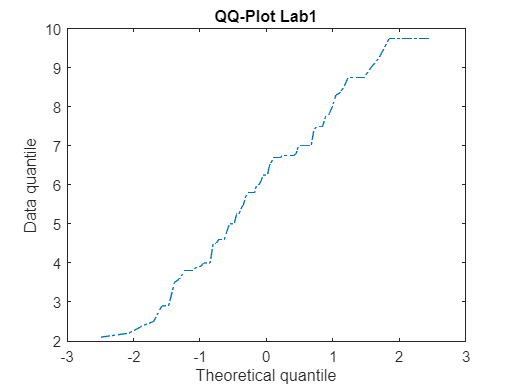

x1 = SMSamplesMarks20192021{:, ["Lab1"]};
n_x1 = length(x1);
q_qqplot = norminv([0.5:n_x1-0.5]/n_x1);
plot(q_qqplot, sort(x1), '-.');
hold on
title('QQ-Plot Lab1');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off

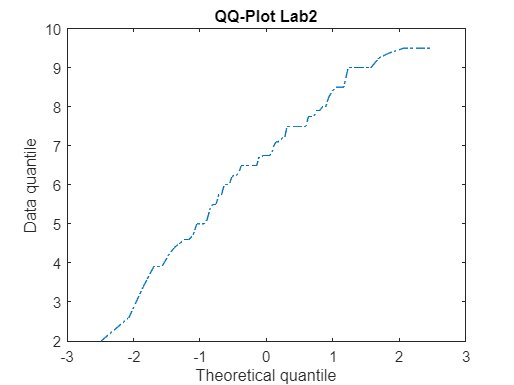


x2 = SMSamplesMarks20192021{:, ["Lab2"]};
plot(q_qqplot, sort(x2), '-.');
hold on
title('QQ-Plot Lab2');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off

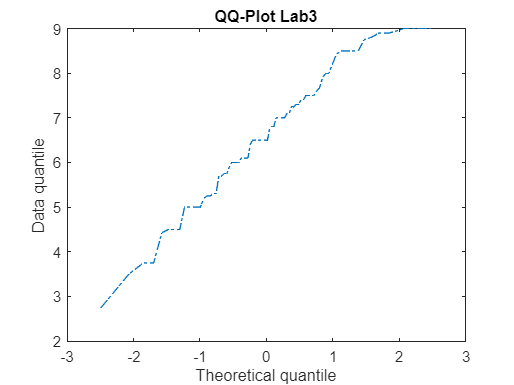


x3 = SMSamplesMarks20192021{:, ["Lab4"]};
plot(q_qqplot, sort(x3), '-.');
hold on
title('QQ-Plot Lab3');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off

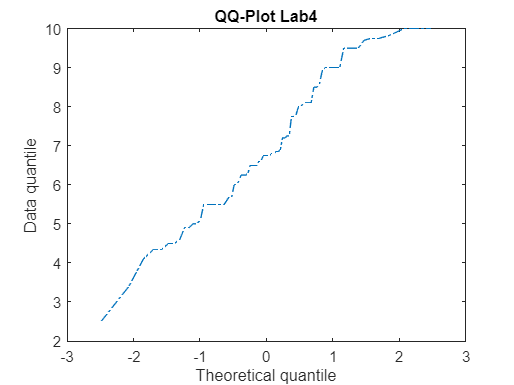


x4 = SMSamplesMarks20192021{:, ["Lab5"]};
plot(q_qqplot, sort(x4), '-.');
hold on
title('QQ-Plot Lab4');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off

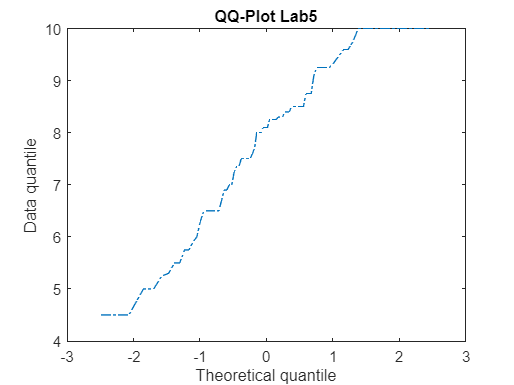


x5 = SMSamplesMarks20192021{:, ["Lab6"]};
plot(q_qqplot, sort(x5), '-.');
hold on
title('QQ-Plot Lab5');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off

Como todos los anteriores qq-plot siguen aproximadamente una línea recta, no podemos rechazar que alguno cumpla los requisitos para univariate normality. Así que primero haremos un estudio de chi-square para cada par de Labs y después uno global con los resultados obtenidos.

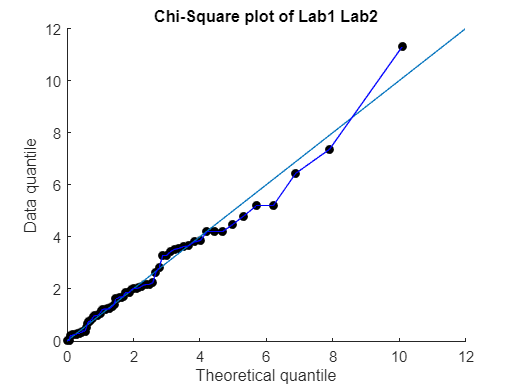

x1x2 = SMSamplesMarks20192021{:, ["Lab1", "Lab2"]};
n_pairs = length(x1x2);
q_chi = chi2inv([0.5:n_pairs-0.5]/n_pairs, 2);

mean1 = mean(x1x2);
cov1 = cov(x1x2);
d_x1x2 = diag((x1x2-mean1)*inv(cov1)*transpose(x1x2-mean1)); 
scatter(q_chi, sort(d_x1x2), '', 'black');
refline(1, min(d_x1x2));            %LÍNEA 45º
hold on
title('Chi-Square plot of Lab1 Lab2');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi, sort(d_x1x2), 'b');
hold off

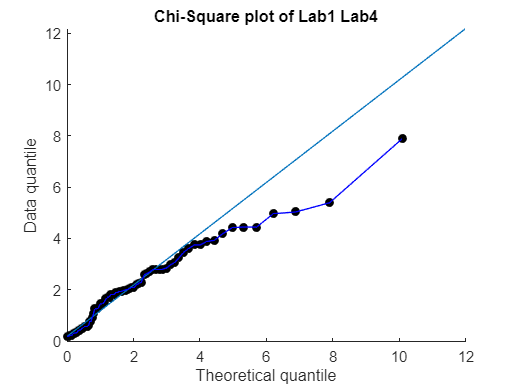


x1x3 = SMSamplesMarks20192021{:, ["Lab1", "Lab4"]};
mean3 = mean(x1x3);
cov3 = cov(x1x3);
d_x1x3 = diag((x1x3-mean3)*inv(cov3)*transpose(x1x3-mean3)); 
scatter(q_chi, sort(d_x1x3), '', 'black');
refline(1, min(d_x1x3));            %LÍNEA 45º
hold on
title('Chi-Square plot of Lab1 Lab4');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi, sort(d_x1x3), 'b');
hold off

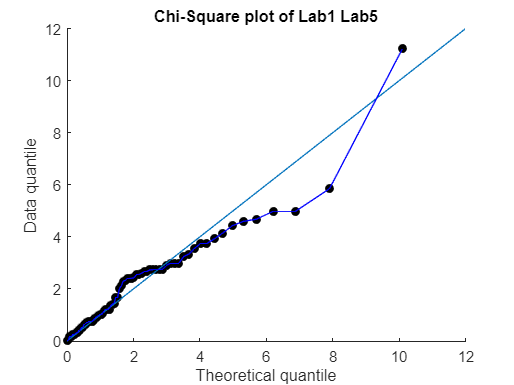


x1x4 = SMSamplesMarks20192021{:, ["Lab1", "Lab5"]};
mean4 = mean(x1x4);
cov4 = cov(x1x4);
d_x1x4 = diag((x1x4-mean4)*inv(cov4)*transpose(x1x4-mean4)); 
scatter(q_chi, sort(d_x1x4), '', 'black');
refline(1, min(d_x1x4));            %LÍNEA 45º
hold on
title('Chi-Square plot of Lab1 Lab5');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi, sort(d_x1x4), 'b');
hold off

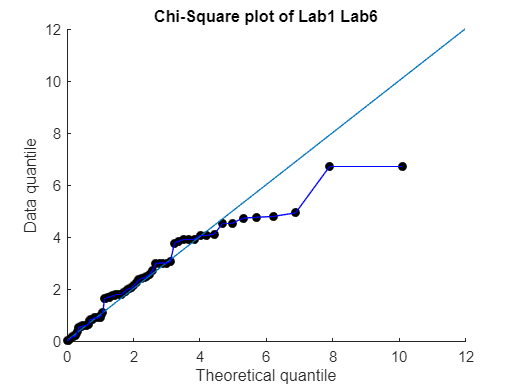


x1x5 = SMSamplesMarks20192021{:, ["Lab1", "Lab6"]};
mean5 = mean(x1x5);
cov5 = cov(x1x5);
d_x1x5 = diag((x1x5-mean5)*inv(cov5)*transpose(x1x5-mean5)); 
scatter(q_chi, sort(d_x1x5), '', 'black');
refline(1, min(d_x1x5));            %LÍNEA 45º
hold on
title('Chi-Square plot of Lab1 Lab6');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi, sort(d_x1x5), 'b');
hold off

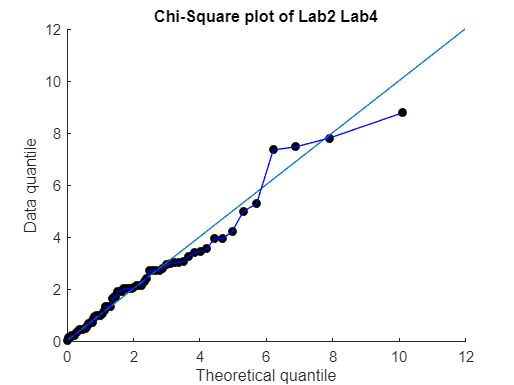


x2x3 = SMSamplesMarks20192021{:, ["Lab2", "Lab4"]};
mean6 = mean(x2x3);
cov6 = cov(x2x3);
d_x2x3 = diag((x2x3-mean6)*inv(cov6)*transpose(x2x3-mean6)); 
scatter(q_chi, sort(d_x2x3), '', 'black');
refline(1, min(d_x2x3));            %LÍNEA 45º
hold on
title('Chi-Square plot of Lab2 Lab4');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi, sort(d_x2x3), 'b');
hold off

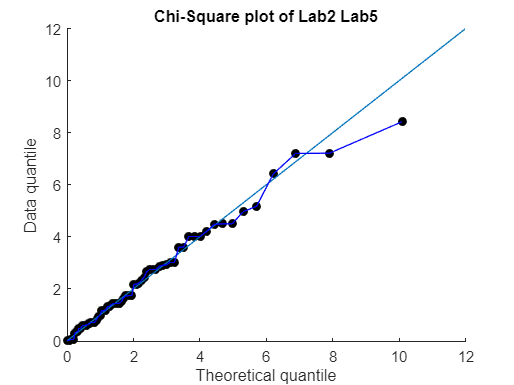


x2x4 = SMSamplesMarks20192021{:, ["Lab2", "Lab5"]};
mean7 = mean(x2x4);
cov7 = cov(x2x4);
d_x2x4 = diag((x2x4-mean7)*inv(cov7)*transpose(x2x4-mean7)); 
scatter(q_chi, sort(d_x2x4), '', 'black');
refline(1, min(d_x2x4));            %LÍNEA 45º
hold on
title('Chi-Square plot of Lab2 Lab5');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi, sort(d_x2x4), 'b');
hold off

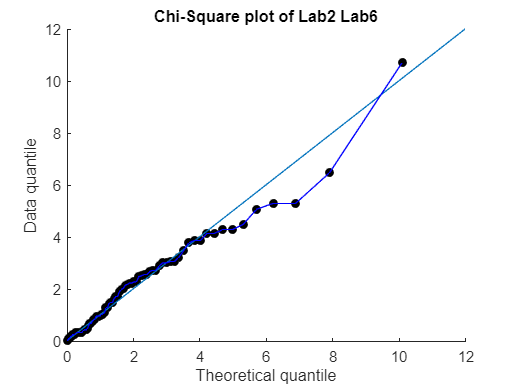


x2x5 = SMSamplesMarks20192021{:, ["Lab2", "Lab6"]};
mean8 = mean(x2x5);
cov8 = cov(x2x5);
d_x2x5 = diag((x2x5-mean8)*inv(cov8)*transpose(x2x5-mean8)); 
scatter(q_chi, sort(d_x2x5), '', 'black');
refline(1, min(d_x2x5));            %LÍNEA 45º
hold on
title('Chi-Square plot of Lab2 Lab6');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi, sort(d_x2x5), 'b');
hold off

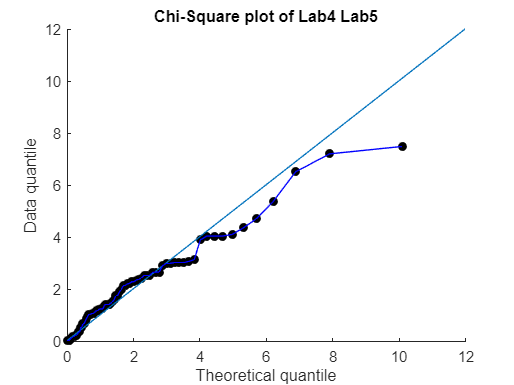


x3x4 = SMSamplesMarks20192021{:, ["Lab4", "Lab5"]};
mean9 = mean(x3x4);
cov9 = cov(x3x4);
d_x3x4 = diag((x3x4-mean9)*inv(cov9)*transpose(x3x4-mean9)); 
scatter(q_chi, sort(d_x3x4), '', 'black');
refline(1, min(d_x3x4));            %LÍNEA 45º
hold on
title('Chi-Square plot of Lab4 Lab5');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi, sort(d_x3x4), 'b');
hold off

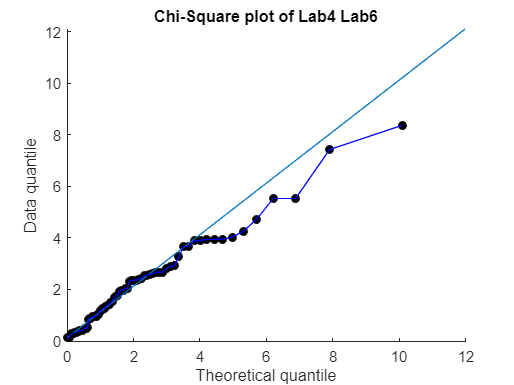


x4x5 = SMSamplesMarks20192021{:, ["Lab4", "Lab6"]};
mean2 = mean(x4x5);
cov2 = cov(x4x5);
d_x4x5 = diag((x4x5-mean2)*inv(cov2)*transpose(x4x5-mean2)); 
scatter(q_chi, sort(d_x4x5), '', 'black');
refline(1, min(d_x4x5));            %LÍNEA 45º
hold on
title('Chi-Square plot of Lab4 Lab6');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi, sort(d_x4x5), 'b');
hold off

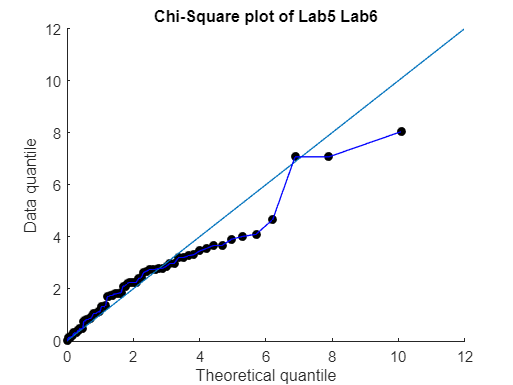


x3x5 = SMSamplesMarks20192021{:, ["Lab5", "Lab6"]};
mean10 = mean(x3x5);
cov10 = cov(x3x5);
d_x3x5 = diag((x3x5-mean10)*inv(cov10)*transpose(x3x5-mean10)); 
scatter(q_chi, sort(d_x3x5), '', 'black');
refline(1, min(d_x3x5));            %LÍNEA 45º
hold on
title('Chi-Square plot of Lab5 Lab6');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi, sort(d_x3x5), 'b');
hold off

A partir de los anteriores plots vemos que los que se asemejan más a tener una normalidad multivariada son los Labs 1, 2 y 4, ya que son los que tienen una mayor relación entre todos ellos según los plots. Finalmente, vemos el chi-square para comprobar que tampoco se puede rechazar que entre ellos tengan una normalidad multivariada.

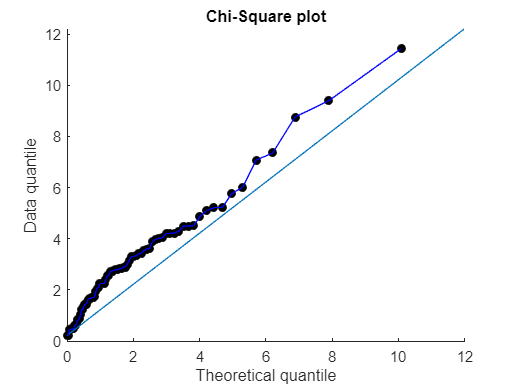

x_tot = SMSamplesMarks20192021{:, ["Lab1", "Lab2", "Lab4"]};
mean11 = mean(x_tot);
cov11 = cov(x_tot);
d_tot = diag((x_tot-mean11)*inv(cov11)*transpose(x_tot-mean11)); 
scatter(q_chi, sort(d_tot), '', 'black');
refline(1, min(d_tot));            %LÍNEA 45º
hold on
title('Chi-Square plot');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi, sort(d_tot), 'b');
hold off

A partir del anterior resultado vemos que el chi-square nos da aproximadamente la línea de 45º, es decir, que no se pueden rechazar que tengan "multivariate normality".

**c) Test the hypotheses stated in (a) with the selected method, regardless of your answer in (b) (i.e. proceed as if the assumptions would hold, no matter whether this is true or not). Indicate what can you conclude about the research question.**

x = SMSamplesMarks20192021{:, ["Lab1", "Lab2", "Lab4", "Lab5", "Lab6"]}; %no tenemos en cuenta el resultado obtenido en (b)
mean_row = mean(x, 2);
mean_col = mean(x, 1);
mean_x = mean(x, 'all');

n = size(x, 1);
g = size(x, 2);

SS_B = n*sum((mean_col-mean_x).^2);
SS_W = sum(sum((x-mean_col).^2));   
SS_subj = g * sum((mean_row-mean_x).^2);
SS_res = SS_W - SS_subj;

estimator = (SS_B/(g-1))/((SS_W-SS_subj)/((n-1)*(g-1)))

estimator = 15.0902

critic = finv(1-alpha, g-1, (n-1)*(g-1))

critic = 2.4017


if (estimator > critic)
    disp("We reject the null hypothesis at significance level 0.017.");
else 
    disp("We cannot reject the null hypothesis at significance level 0.017.");
end

We reject the null hypothesis at significance level 0.017.


Una vez realizado el test, podemos ver como el estimador es mayor al valor critico, en consecuencia rechazamos el hecho de que todos los labs tengan la misma dificultad.

**d) The following question depends on what you answer in (c):**

**    • If you conclude that some of the labs are more difficult than others, use post-hoc tests to determine: **

**        c1) Is their any lab that is significantly more difficult than all other labs?**

**        c2) Is their any lab that is significantly easier than all other labs?**

**    • Otherwise, compute confidence intervals for the difference of the average lab marks (for all pairs of labs). Verify whether these                 intervals confirm your findings in (c).**

mean_1 = mean(x(:,1), 1)

mean_1 = 6.0428

mean_2 = mean(x(:,2), 1)

mean_2 = 6.6734

mean_4 = mean(x(:,3), 1)

mean_4 = 6.5296

mean_5 = mean(x(:,4), 1)

mean_5 = 6.8451

mean_6 = mean(x(:,5), 1)

mean_6 = 7.7678


N = n*g;
M = g*(g-1)/2

M = 10

tcrit = tinv(alpha/(2*M), N-g)

tcrit = -2.8237

denominator = sqrt((SS_W/(N-g))*(1/n+1/n));
T_12 = (mean_1-mean_2)/denominator

T_12 = -2.3722

T_14 = (mean_1-mean_4)/denominator

T_14 = -1.8315

T_15 = (mean_1-mean_5)/denominator

T_15 = -3.0182

T_16 = (mean_1-mean_6)/denominator

T_16 = -6.4893

T_24 = (mean_2-mean_4)/denominator

T_24 = 0.5408

T_25 = (mean_2-mean_5)/denominator

T_25 = -0.6459

T_26 = (mean_2-mean_6)/denominator

T_26 = -4.1171

T_45 = (mean_4-mean_5)/denominator

T_45 = -1.1867

T_46 = (mean_4-mean_6)/denominator

T_46 = -4.6579

T_56 = (mean_5-mean_6)/denominator

T_56 = -3.4712

De los resultados vemos que se rechazan T_15, T_16, T_26, T_46, T_56. Vemos que el factor en común de todo lo que rechazamos son el Lab5 y el Lab6, por lo que la conclusión seria que los Lab 5 y 6 tienen diferente dificultad que los labs 1,2,4 que no podemos rechazar que tengan la misma dificultad. %No se como decir cual es más dificil y cual más facil, porque aqui solo vemos que es diferente sabes? nose si los que rechazamos son mas dificiles? es q no creo nose. Lo que es seguro es lo que he puesto hasta el comentario, a partir de ahi..